## Statistical Hypothesis Testing (16/02/2021)

The third lab of the Intro to Data Science course looks at Statistical Hypothesis Testing. This refers to process of investigating the statistical significance of a hypothesis or assumption, and quantifying whether or not this is large enough to separate the outcome from random chance. 

The steps are largely as follows:

- We observe a difference between two sets of observations

- We measure a test statistic (e.g. difference in mean)

- We postulate a null-hypothesis / random process generating the two events

- We observe the test statistic between sets of observations generated under the null hypothesis

- We compute the probability of an outcome with as large an effect as that observed, under the null hypothesis / p-value

- We compare two hypotheses - an alternative hypothesis (H1), and a null hypothesis (H0), the latter of which represents the effect of random chance

- If our p-value is lower than our threshold, i.e. is statistically significant, we then reject H0

We will conduct a small investigation using both the Temperature and Titanic Datasets, in order to put the theory into practise.

### Experiment 1) Investigating the hypothesis (h1) that the temperature in July is greater than that in January through simulation

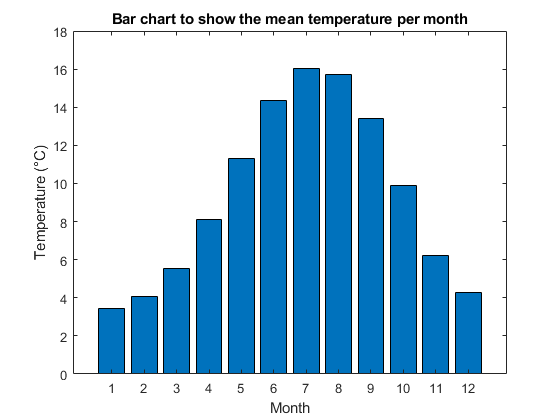

% Begin by importing data, replacing placeholders, and scaling
run('Import_Data.m');

% Then we can plot the mean temperatures per month
figure;
bar(mean(data, "omitnan"))
ylabel("Temperature (°C)");
xlabel("Month");
title("Bar chart to show the mean temperature per month")

Looking at the plot, it is clear that that the mean temperature appears to vary over the year, however can we be sure about this? For instance, is it accurate to say that the temperature in July are statistically warmer than those in January, or that a typical day in July will be warmer than that in January?

We can investigate this by using statistical hypothesis testing, more precisely, by comparing the probability of seeing a difference in temperature between months 1 (January) and 7 (July), to that observed between two randomly formed set. If the temperature difference (or effect size) is much larger for our selected sets than for two randomly formed sets, then we can conclude that our observation is statistically significant, and that there is an underlying difference between their data-generation processes.

The null hypothesis refers to the outcome being caused by a random generation process, whereas the alternative hypothesis refers to our suspicion of there being a separate, distinct, and bias generation process at play, in our case being a distinct temperature difference between that in January and July.

One way of investigating this would be to randomly shuffle the monthly data and compare the temperature difference (or effect size) between sets 1 and 7 for our original unshuffled data, and for our randomised data. We shall now do that.

% Preallocate array
shuffledData = zeros(7719,12);

% Iterate through all rows and randomly shuffle the monthly values
for i = 1:7719
    shuffledData(i,:) = data(i,randperm(12));
end

We can now compare the shuffled and original data

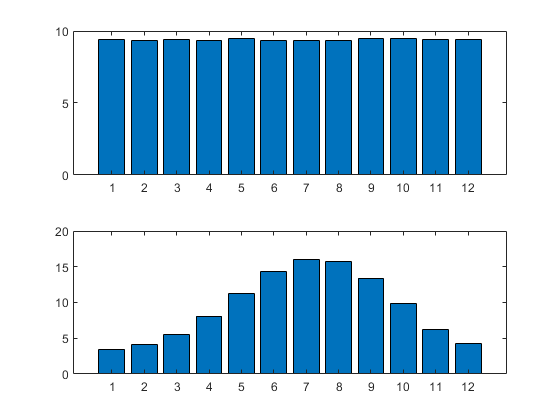

figure;

% Plotting the shuffled data
subplot(2,1,1);
bar(mean(shuffledData, "omitnan"));

% Plotting the original data
subplot(2,1,2);
bar(mean(data, "omitnan"));

This shuffling process can be repeated as many times as we wish, and we could use this process to estimate the probability of a random assignment of days to months that create such a clear difference between January and July. In other words, we shuffle this data, find the resulting difference between sets 1 and 7, and see how probable it is for the difference to be as large as we observe using the real-world data.

We can investigate this through the use of a test statistic. A simple example might be the difference in mean between the two sets (January and July), which we could measure N = 1000 times on the shuffled data, and compare how often a value equal to or larger than the observed effect is seen.

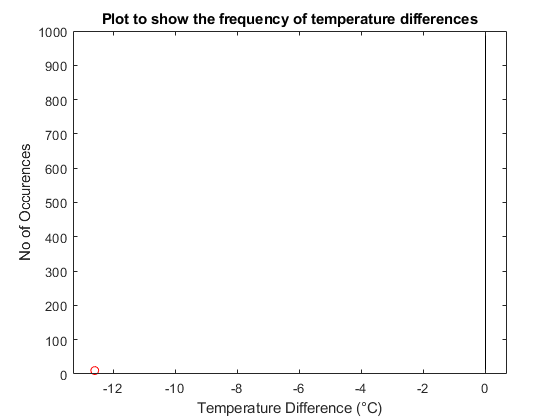

% First we create our test statistic on the real data
test_statistic = mean(data(:,1),"omitnan") - mean(data(:,7),"omitnan");

% We shuffle the data N = 1000 times, and calculate the same statistic
shuffledStatistic = zeros(1000,1);
for k = 1000
    for i = 7719
        shuffledData(i,:) = data(i,randperm(12));
    end
    statistic = mean(shuffledData(:,1),"omitnan") - mean(shuffledData(:,7),"omitnan");
    shuffledStatistic(k) = statistic;
end

figure;
histogram(shuffledStatistic);
hold on;
plot(test_statistic_means, 10, "ro");
ylabel("No of Occurences");
xlabel("Temperature Difference (°C)");
title("Plot to show the frequency of temperature differences");
xlim([-13.3 0.7])
ylim([0 1000])

In the plot above, we see that the temperature difference observed between January and July of -12.5 degrees Celsius has a substantially greater magnitude than that observed from randomly shuffled months (at around 0 degrees Celsius). The gap between the two temperature difference observations is large, and we never see a random difference being as large as the actual value. This implies that the probability of seeing the observed temperature difference by chance is less than 1/1000.

Reframing or recapping our investigation, we did the following:

- we were asking what is the probability of observing our difference (**effect size**) between January and July.

- Our hypothesis was there there is a connection between the month of the year and daily temperature.

- We tested this hypothesis by generating 1000 random assignments, with the null hypothesis being that the daily temperature is NOT correlated with the month of the year.

- Looking at our plot comparing the mean differences for our 1000 random assignment and the observed mean difference, we find that the observed effect is never achieved by random allocation.

- Under the null hypothesis, the probability of observing the effect is p<1/1000 (**p-value**)

- We set a **significance threshold** of alpha = 1/100 (or 0.01)

- Hence, we can conclude that the observed difference is **statistically significant** (and is not the result of random chance)

Difference of means is not the only test statistic, another being a consideration of the means and standard deviation between the two sets (or two-sample location test), which may be appropriate given the normally distributed temperatures observed per month, as seen in the Temperature investigation last week. This statistic is demonstrated below.

difference_in_means = mean(data(:,7),"omitnan") - mean(data(:,1),"omitnan");
combined_std = sqrt(var(data(:,7),"omitnan") + var(data(:,1),"omitnan"));
normal_statistic = 1/sqrt(7719) * (difference_in_means/combined_std)

normal_statistic =    0.034693858031967


The value of the test statistic is 0.0347. We could then compute this for randomised data, as before, in order to assess statistical significance. A similar / same conclusion would be expected, with the p-value being smaller than the test-statistic, hence deeming this observation statistically significant, and informing the rejection of the null hypothesis, h0.

### Experiment 2) Investigating the hypothesis that the temperature in July is greater than that in January analytically (without random permutation / simulation)

We have looked at using random permutation to investigate statistical significance, but what about analytical methods? The Student t-test is one way of evaluating this, using the same two-sample location test shown above, assuming that our samples are sampled from 2 gaussians.

The null hypothesis is that the mean is the same.

The alternative hypothesis is that the mean is different.

We can compute the test statistic from above, or use the included ttest2 function within Matlab. This command returns a test decision for the null hypothesis that the data comes from independent random samples from normal distributions with equal means and equal but unknown variance, using the two-sample t-test. The alternate hypothesis is that they come from populations with unequal means, and the result of the command is 1 if the null hypothesis is rejected at the 5% significance level, and 0 otherwise.

% Compute the two-sample t-test for January and July vectors
h = ttest2(data(:,1), data(:,7))

h =      1


Here, our result is 1, confirming our findings from before, i.e. the null hypothesis is rejected, and we accept the alternative hypothesis, as it is statistically significant at the 5% significance level.

As further intuition into the test statistic, we are computing the difference between the data we observe, and that which would be expected under the null hypothesis, which is divided by the average variation. The test statistic can therefore be viewed as a sort of discrepancy or loss, with a smaller test statistic indicating closer agreement or overlap between the two groups, which can be achieved through both the value of mean and variance.

Another way of looking at this is as a signal-to-noise ratio, or ratio of between group variance vs within group variance, serving to illustrate or measure the separability between the two groups. Less separability illustrates a closer agreement, and single distribution, whereas high separability indicates the presence of two distinct groups. It is important to note that bigger samples are required, and that small samples do not have enough statistical power to prove that difference actually exist.

### Experiment 3) Investigating if there is a significant relation between Class and Fare, i.e. does a higher class correspond with a higher fare?

Our null hypothesis is that the class and fare are independent (or random)

Our alternative hypothesis is that class and fare are correlated (higher class = higher fare)

We start by choosing a test statistic, e.g. difference in average fare. We can compute this on our actual dataset, which forms our p-value.

We can then randomly assign passengers to a class, and calculate the same test statistic, and observe how often the same difference is seen in the randomised data as per our actual observation.

By comparing the results, we can establish whether the observation is statistically significant to our chosen significance level (e.g. 5%), and then reject / accept the relevant hypothesis.

We will now conduct this investigation using the methodology outlined above.

% We first import the data
data = readtable("./data/titanic.csv");

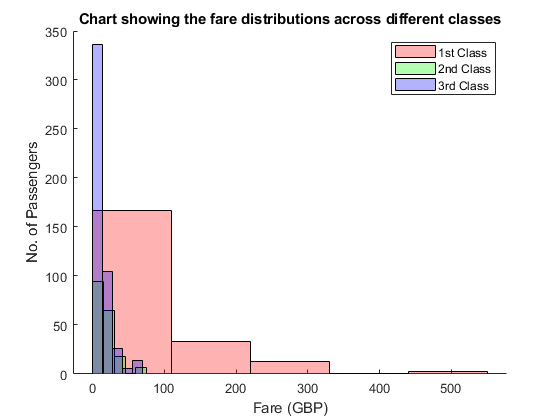

% We then extract the columns of interest
class = data.Pclass;
fare = data.Fare;

% We can then extract subsets of the fare per class
fare1 = fare(class==1);
fare2 = fare(class==2);
fare3 = fare(class==3);

% We can plot these for a visual comparison
figure;
hold on;
histogram(fare1, 5, "EdgeColor", "black", "FaceColor", ...
    "red", "FaceAlpha", 0.3, "DisplayName", "1st Class");
histogram(fare2, 5, "EdgeColor", "black", "FaceColor", ...
    "green", "FaceAlpha", 0.3, "DisplayName", "2nd Class");
histogram(fare3, 5, "EdgeColor", "black", "FaceColor", ...
    "blue", "FaceAlpha", 0.3, "DisplayName", "3rd Class");
ylabel("No. of Passengers");
xlabel("Fare (GBP)");
title("Chart showing the fare distributions across different classes");
legend();
hold off;

Now we can compute our test statistics and test our hypothesis that passenger class and ticket fare are correlated. We will do this using only two of the three classes, namely first and third class, and our test statistic will be the difference of means.

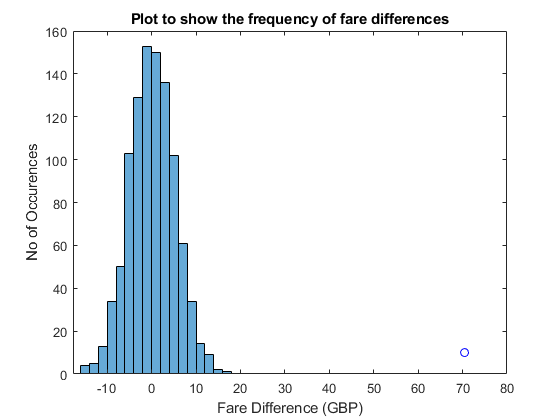

% Compute test statistic for observed data
observed_statistic = mean(fare1) - mean(fare3);

% Combine the data for 1st and 3rd classes into one vector
combined_data = vertcat(fare1, fare3);

% Extend the vector with a row for classes
combined_data = horzcat(ones(length(combined_data),1), combined_data);

% Simulate random dataset
shuffled_statistics = zeros(1000,1);
for shuffle_iter = 1:1000
    
    % Assign randomised classes
    for column_iter = 1:size(combined_data, 1)
        combined_data(column_iter,1) = randi([1, 3], 1);
    end
    
    % Extract randomised class sets, and compute difference of means
    random_fare1 = combined_data(combined_data(:,1) == 1, 2);
    random_fare3 = combined_data(combined_data(:,1) == 3, 2);
    shuffled_statistics(shuffle_iter) = mean(random_fare1) - mean(random_fare3);    
end

figure;
histogram(shuffled_statistics);
hold on;
plot(observed_statistic, 10, "bo");
ylabel("No of Occurences");
xlabel("Fare Difference (GBP)");
title("Plot to show the frequency of fare differences");

From the plot, it is evident that the mean fare difference observed between first and third class (approximately £70) is far greater than that observed from random assignments, with the plot illustrating a chance of less than 1/100 of this effect being caused by random chance. As such, we can conclude that the result is statistically significant (it is less likely to occur than our selected 1% significance level), and so can reject the null hypothesis. We accept the alternative hypothesis, being that there is a correlation between passenger class and ticket fare, and more precisely that a more exclusive passenger class typically results in a higher ticket fare.